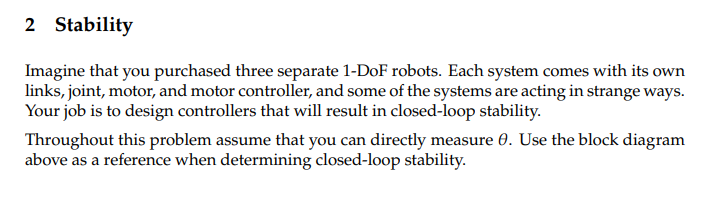

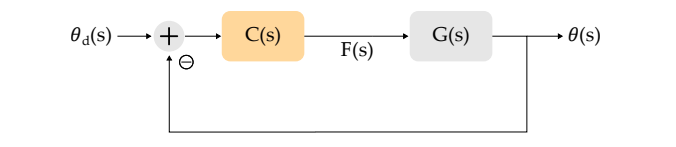

syms C G theta_d theta real

eqn = G*(C*(theta_d - theta)) == theta;
eqn = solve(eqn, theta)/theta_d

$$eqn = \frac{C\,G}{C\,G+1}$$

[~,denom] = numden(eqn)

$$denom = C\,G+1$$

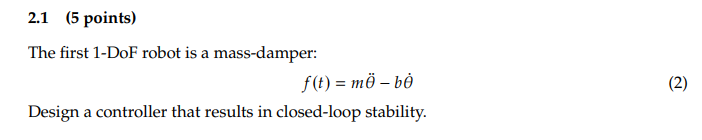

syms theta m b s F real

laplacian = m*s^2 - b*s

$$laplacian = m\,s^{2}-b\,s$$

g = 1/laplacian

$$g = -\frac{1}{b\,s-m\,s^{2}}$$

c = 7*b*s + 4 % Choosing a controller

$$c = 7\,b\,s+4$$

eqn = subs(denom, [C,G], [c,g]) == 0

$$eqn = 1-\frac{7\,b\,s+4}{b\,s-m\,s^{2}}=0$$

eqn = subs(eqn, [m,b], [1,1])

$$eqn = 1-\frac{7\,s+4}{s-s^{2}}=0$$

verification = round(vpasolve(eqn, s), 4) % Both are real negative values

$$verification = \left(\begin{array}{c} -5.2361\\ -0.7639 \end{array}\right)$$

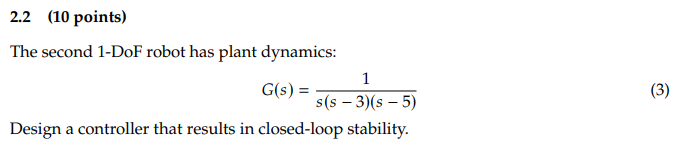

laplacian = (s*(s-3)*(s-5))

$$laplacian = s\,\left(s-3\right)\,\left(s-5\right)$$

g = 1/laplacian

$$g = \frac{1}{s\,\left(s-3\right)\,\left(s-5\right)}$$

c = 20*s^2 + 19 % Choosing a controller

$$c = 20\,s^{2}+19$$

eqn = subs(denom, [C,G], [c,g]) == 0

$$eqn = \frac{20\,s^{2}+19}{s\,\left(s-3\right)\,\left(s-5\right)}+1=0$$

verification = round(vpasolve(eqn, s), 4) % Both are negative values that lie on the left side of the plane which is correct in controls

$$verification = \left(\begin{array}{c} -10.7712\\ -0.6144+1.1775\,\mathrm{i}\\ -0.6144-1.1775\,\mathrm{i} \end{array}\right)$$

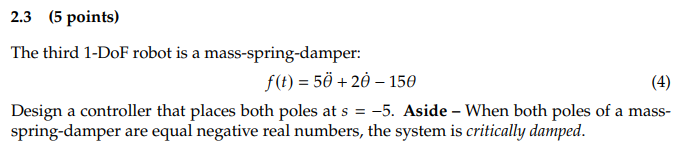

laplacian = 5*s^2+ 2*s - 15

$$laplacian = 5\,s^{2}+2\,s-15$$

g = 1/laplacian

$$g = \frac{1}{5\,s^{2}+2\,s-15}$$

c = 48*s + 140 % Choosing a controller

$$c = 48\,s+140$$

eqn = subs(denom, [C,G], [c,g]) == 0

$$eqn = \frac{48\,s+140}{5\,s^{2}+2\,s-15}+1=0$$

verification = solve(eqn, s) % Verification that the poles are -5

$$verification = -5$$